
clear variables;



close all;

filedir1 = "D:\Data\Lattice_RIN\20240612\24_06_12frequency_0612_On2.txt";

savedir = '\\Artemis-pc\e\Data\2024-06-12\1036Seed_RIN\';
mkdir(savedir);


current = 12;   % 激光器电流
AM = 8;   % amplitude modulation
RF = 0;   % 射频功率

PD = 4.13;   % 透射端 PD 电压 V

power_mW = PD^2/50*1e3;   % mW
power_dBm = 10*log10(power_mW);   % dBm

[freq,intensity_dBm1] = importfile(filedir1);

filedir2 = "D:\Data\Lattice_RIN\20240612\24_06_12frequency_0612_On3.txt";
[freq,intensity_dBm2] = importfile(filedir2);

filedir3 = "D:\Data\Lattice_RIN\20240612\24_06_12frequency_0612_On4.txt";
[freq,intensity_dBm3] = importfile(filedir3);

filedir4 = "D:\Data\Lattice_RIN\20240612\24_06_12frequency_0612_On5.txt";
[freq,intensity_dBm4] = importfile(filedir4);

intensity_dBm = (intensity_dBm1+intensity_dBm2+intensity_dBm3+intensity_dBm4)/4;

filedir5 = "D:\Data\Lattice_RIN\20240612\24_06_12frequency_0612_Off1.txt";
[freq,BG_dBm1] = importfile(filedir5);

filedir6 = "D:\Data\Lattice_RIN\20240612\24_06_12frequency_0612_Off2.txt";
[freq,BG_dBm2] = importfile(filedir6);

filedir7 = "D:\Data\Lattice_RIN\20240612\24_06_12frequency_0612_Off3.txt";
[freq,BG_dBm3] = importfile(filedir7);

BG_dBm = (BG_dBm1+BG_dBm2+BG_dBm3)/3;




close all;

RIN1 = intensity_dBm-2*power_dBm;

BG1 = BG_dBm-2*power_dBm;

%ref = -33.77-RIN1(2);
%RIN1 = ref+RIN1;
freq_k = freq./1e0;   % kHz

h1 = figure;
plot(freq_k,RIN1,'.-','MarkerSize',12,'Color',[0.2 0.69 0.86]);
hold on;
plot(freq_k,BG1,'.-','MarkerSize',12);
%ylim([-152 -149]);
xlim([0.9 100]);
grid on;6

ans = 6

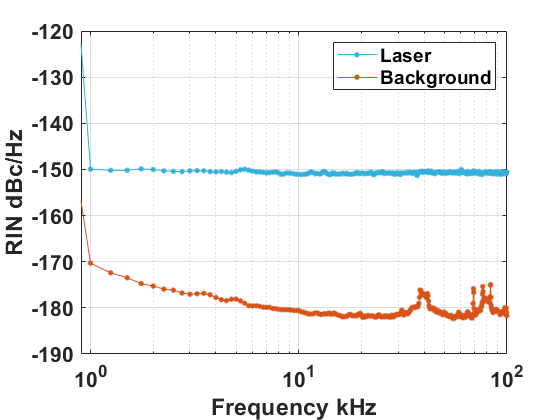

set(gca,'FontName','Arial','FontWeight','bold','FontSize',16);
xlabel('Frequency kHz');
ylabel('RIN dBc/Hz');
%legend(['VCA: ','AM ',num2str(AM,'%.1f'),'V'],'Location','best');
%legend(['current ',num2str(current),'A',newline 'RF ',num2str(RF,'%.1f'),'dBm'],'Location','best');
legend('Laser','Background');

set(gca,'XScale','log');
set(gcf,'Visible','on');


% savefig(h1,[savedir,'RIN_elec_pow.fig']);
% saveas(h1,[savedir,'RIN_elec_pow.png']);
% 
% save([savedir,'\RIN_elec_pow.mat']);


savefig(h1,[savedir,'RIN_BackGround.fig']);
saveas(h1,[savedir,'RIN_BackGround.png']);


save([savedir,'\RIN_BackGround.mat']);

function [freq, intensity] = importfile(filename, dataLines)
%% 输入处理

% 如果不指定 dataLines，请定义默认范围
if nargin < 2
    dataLines = [1, Inf];
end

%% 设置导入选项并导入数据
opts = delimitedTextImportOptions("NumVariables", 2);

% 指定范围和分隔符
opts.DataLines = dataLines;
opts.Delimiter = "\t";

% 指定列名称和类型
opts.VariableNames = ["freq", "intensity"];
opts.VariableTypes = ["double", "double"];

% 指定文件级属性
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% 导入数据
tbl = readtable(filename, opts);

%% 转换为输出类型
freq = tbl.freq;
intensity = tbl.intensity;
end